clear all;
clc;

fs = 11025;           
num_samples = 816000;   
t = (0:num_samples-1) / fs;  
T = num_samples / fs; 


f1_start = 850;          % 第一个信号的起始频率（Hz）
f1_end = 1850;         % 第一个信号的结束频率（Hz）

f2_start = 1200;          % 第一个信号的起始频率（Hz）
f2_end = 1950+750;         % 第一个信号的结束频率（Hz）

f3_start = 50;          % 第一个信号的起始频率（Hz）
f3_end = 1050;         % 第一个信号的结束频率（Hz）

f4 = 1940;       % 第二个信号的起始频率（Hz）
f5 = 1950;         % 第二个信号的结束频率（Hz）

frequency_variation_1 = f1_start + (f1_end - f1_start) * (0.5 * (1 + sin(2 * pi * t / T)));  
sinusoidal_noise_1 = sin(2 * pi * cumsum(frequency_variation_1) / fs);

frequency_variation_2 = f2_start + (f2_end - f2_start) * (0.5 * (1 - sin(2 * pi * t / T)));  
sinusoidal_noise_2 = sin(2 * pi * cumsum(frequency_variation_2) / fs);

frequency_variation_3 = f3_start + (f3_end - f3_start) * (0.5 * (1 + sin(2 * pi * t / T)));  
sinusoidal_noise_3 = sin(2 * pi * cumsum(frequency_variation_3) / fs);

sinusoidal_noise_4 = sin(2 * pi * f4 * t);

sinusoidal_noise_5 = sin(2 * pi * f5 * t );



frequency_variation_1_1 = f1_start + (f1_end - f1_start) * (0.5 * (1 + sin(2 * pi * t / T)));  
sinusoidal_noise_1_1 = cos(2 * pi * cumsum(frequency_variation_1_1) / fs);

frequency_variation_2_1 = f2_start + (f2_end - f2_start) * (0.5 * (1 - sin(2 * pi * t / T))); 
sinusoidal_noise_2_1 = cos(2 * pi * cumsum(frequency_variation_2_1) / fs);

frequency_variation_3_1 = f3_start + (f3_end - f3_start) * (0.5 * (1 + sin(2 * pi * t / T)));  
sinusoidal_noise_3_1 = cos(2 * pi * cumsum(frequency_variation_3_1) / fs);

sinusoidal_noise_4_1 = cos(2 * pi * f4 * t );

sinusoidal_noise_5_1 = cos(2 * pi * f5 * t );



combined_signal = sinusoidal_noise_1 + sinusoidal_noise_2 + sinusoidal_noise_3 + sinusoidal_noise_4 + sinusoidal_noise_5;

combined_signal_1 = sinusoidal_noise_1_1 + sinusoidal_noise_2_1 + sinusoidal_noise_3_1 + sinusoidal_noise_4_1 + sinusoidal_noise_5_1;

combined_signal_2 = combined_signal+ combined_signal_1;
combined_signal_2

combined_signal_2 =     6.0134    5.2985    0.6852   -3.2323   -2.7958    0.9840    3.7266    2.4792   -1.2581   -3.4727   -2.2141    0.3609    0.6885   -1.9169   -4.3254   -3.1384    1.2536    4.7524    3.8617   -0.4454   -3.6013   -2.2242    2.3250    5.4284    4.0966   -0.0343   -2.7298   -1.8246    0.6466    1.0812   -1.4091   -3.9585   -3.3124    0.2543    2.9926    1.7828   -2.2419   -4.6731   -2.4907    2.6151    5.9104    4.5174    0.2923   -2.3424   -1.1493    1.7731    2.6408    0.3218   -2.5120   -2.6158



combined_signal_2 = combined_signal_2';

Sn_ref = [combined_signal_2, combined_signal_2];  
sn_ref_matirx = [sinusoidal_noise_1;sinusoidal_noise_1_1;sinusoidal_noise_2;sinusoidal_noise_2_1;sinusoidal_noise_3;sinusoidal_noise_3_1;sinusoidal_noise_4;sinusoidal_noise_4_1;sinusoidal_noise_5;sinusoidal_noise_5_1];
sn_ref_matirx

sn_ref_matirx =     0.6957    0.9995    0.7403    0.0641   -0.6482   -0.9954   -0.7818   -0.1278    0.5982    0.9872    0.8201    0.1910   -0.5457   -0.9750   -0.8550   -0.2534    0.4910    0.9588    0.8864    0.3147   -0.4343   -0.9386   -0.9142   -0.3747    0.3759    0.9147    0.9382    0.4331   -0.3160   -0.8870   -0.9584   -0.4898    0.2548    0.8558    0.9746    0.5444   -0.1926   -0.8211   -0.9869   -0.5967    0.1297    0.7830    0.9952    0.6466   -0.0662   -0.7418   -0.9994   -0.6939    0.0026    0.6976
    0.7183    0.0320   -0.6723   -0.9979   -0.7614   -0.0960    0.6235    0.9918    0.8014    0.1595   -0.5722   -0.9816   -0.8380   -0.2223    0.5186    0.9674    0.8712    0.2842   -0.4629   -0.9492   -0.9008   -0.3449    0.4053    0.9271    0.9267    0.4041   -0.3461   -0.9013   -0.9488   -0.4617    0.2855    0.8719    0.9670    0.5173   -0.2238   -0.8388   -0.9813   -0.5709    0.1612    0.8024    0.9916    0.6220   -0.0980   -0.7628   -0.9978   -0.6706    0.0344    0.7201   

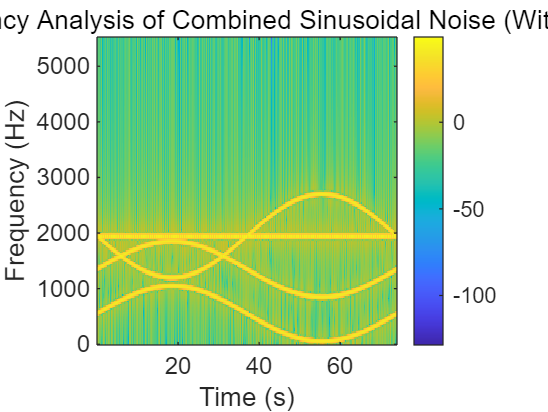


save('Sn_ref_d1.mat', 'Sn_ref','sn_ref_matirx');

N = 400;               
L = N / 2;  
window = hamming(N); 
figure;
[S, F, T_spec] = spectrogram(combined_signal, window, L, N, fs);
imagesc(T_spec, F, 20*log10(abs(S)));  
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Time-Frequency Analysis of Combined Sinusoidal Noise (With Phase)');
colorbar;